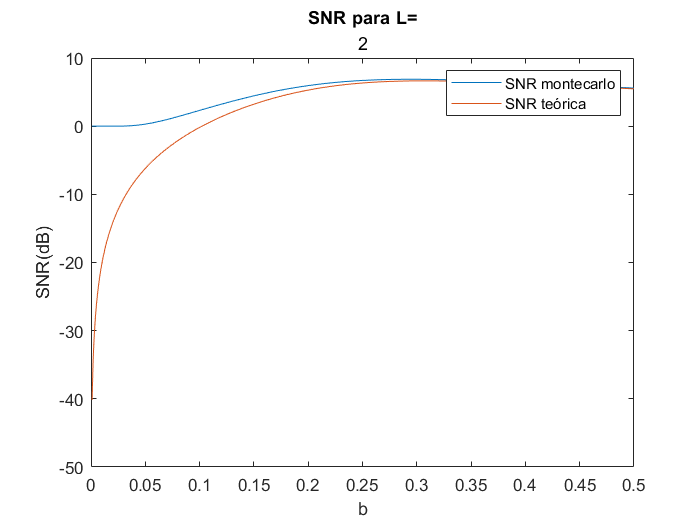

La SNR óptima es:


    6.8793



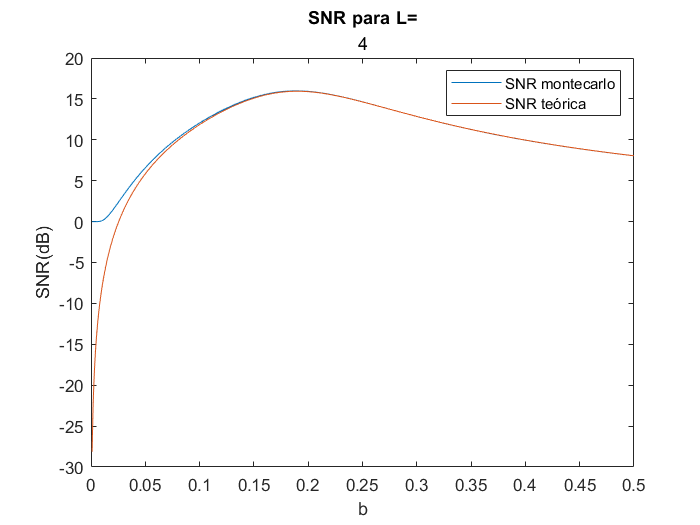

La SNR óptima es:


   15.9779



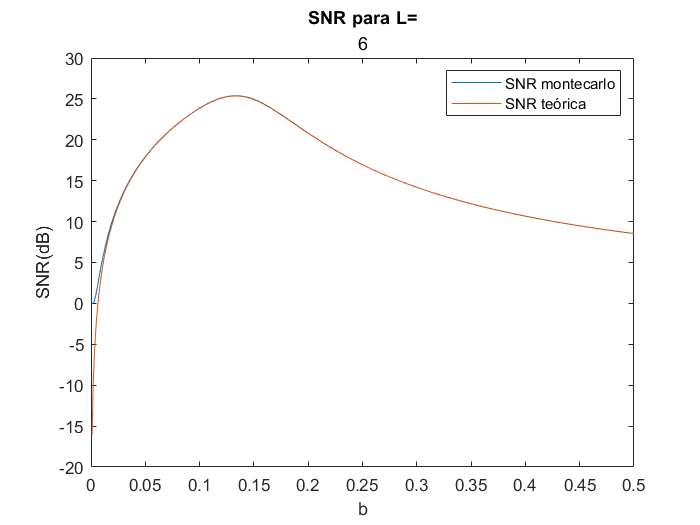

La SNR óptima es:


   25.3928



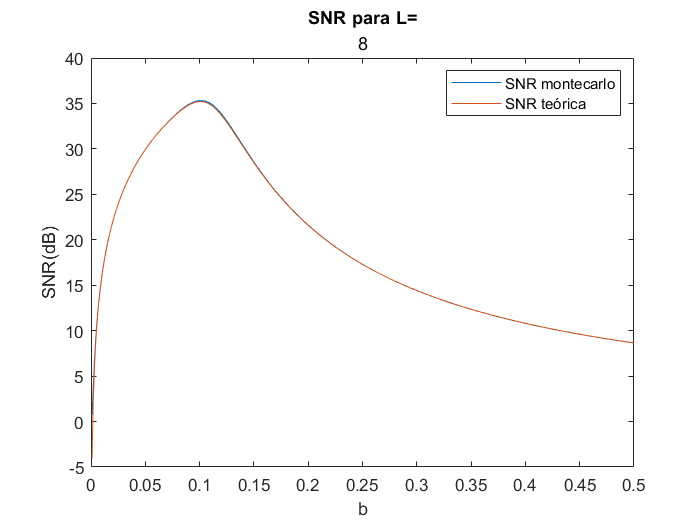

La SNR óptima es:


   35.3175



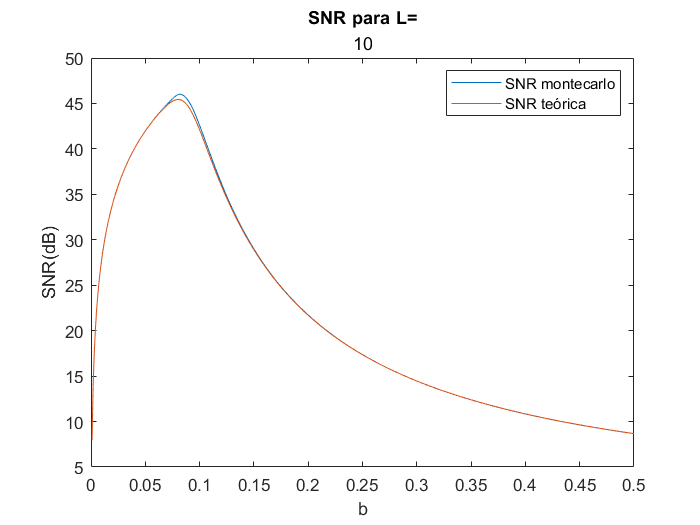

La SNR óptima es:


   46.0221



close all;
clear

% VARIABLES

valores_L = 2:2:10; %Rango de valores de L
u=rand([1,1000000]);
SNR=[];
var_signal=[];
var_teorico =[]; 
SNR_teorica=[];
var_E=[];

% CALCULO SNR

for counter = 1:length(valores_L)
    L = valores_L(counter);
    delta=2/(2^L);
    i=1; %Variable auxiliar
    mincent=-1; %Primer centroide
    maxcent=1-delta; %Último centroide
    b=0.001; %Salto del valor de b
    ran_b= 0:b:0.5; %Rango de valores de b
    for b = ran_b
        
        %formula teorica
        signal = (-b)*sign(u-0.5).*log(1-2*abs(u-0.5)); % Señal Laplaciana con media 0
        %signal = laprnd(u, 1, mu, b);
        var_signal(i)=var(signal);
        Q = delta * round(signal/delta); %Calculamos el valor del cuantificador
        Q(Q > maxcent) = maxcent; %Si el valor es mayor al último centroide le asignamos el valor del centroide
        Q(Q < mincent) = mincent; %Si el valor es menor al primer centroide le asignamos el valor del centroide
        E = signal - Q; %Calculamos el error como la entrada menos el cuantificador
        var_E(i) = var(E);
        SNR(i) = var_signal(i) / var_E(i); %Calculamos la SNR 
        %SNR(i) = 2*b^2./ var_E(i);
        
        %%Cálculo teórico de la SNR

        terminouno = @(E) (E.^2)*(1/(2*b)).*exp((-1+E)/b); %primera integral
        terminodos = (1-(0.5*(exp((-delta-2)/(2*b)) +exp((delta-2)/(2*b)))))*(delta^2); %resultado de la segunda integral realizada a mano
        terminotres = @(E) (E.^2)*(1/(2*b)).*exp ((-1-E+delta)/b); %tercera integral
        integral1 = integral(terminouno, -Inf,-delta/2);
        integral3= integral(terminotres, delta/2, inf);
        
        varteorica = integral1 + (terminodos/12) + integral3;
        SNR_teorica(i) = (2*b^2)/varteorica; %Calculo de la SNR teórica
        i=i+1;

    end

    %Grafica de la SNR en funcion de b para un L concreto
    figure;
    x_norm = (ran_b)'; %Normalización del eje x
    plot(x_norm, 10*log10(SNR));
    
    xlabel('b');
    ylabel('SNR(dB)');
    title('SNR para L=',num2str(L));
    hold on
    plot(x_norm,10*log10(SNR_teorica));
    legend('SNR montecarlo', 'SNR teórica');
    [valormax, indicemax] = max(10*log10(SNR));%Hallamos la SNR óptima para cada valor de L y la mostramos junto a las gráficas
    disp('La SNR óptima es:')
    disp(valormax)
end